clc;clear;

mdlName="gaussian_product";

## Prepare fuzzy controller

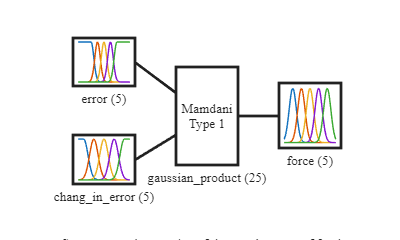

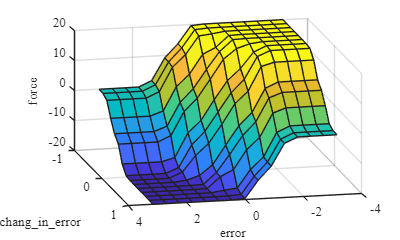

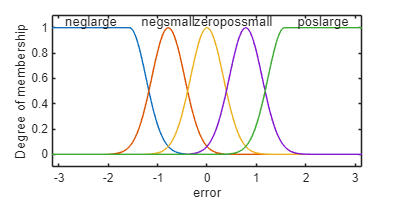

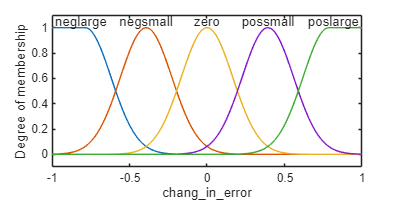

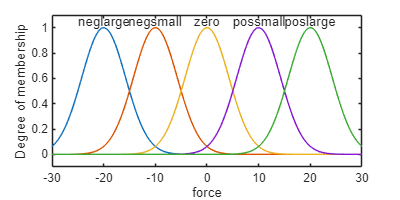

fis = readfis("assets/"+mdlName);
visualizeFIS(fis,mdlName);

## Set derivative gain

deriv_gain_set = [
    % g0 g1 h
    [1 1 1]
    [1 0.1 1]
    [2 0.1 1]
    [2 0.1 5]
    [5 1 1]
    ];

## Start Simulink

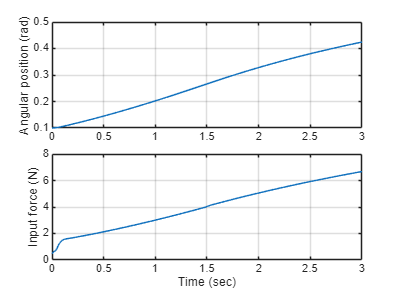

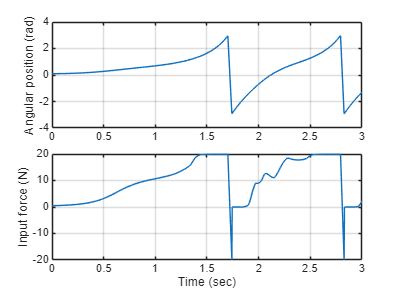

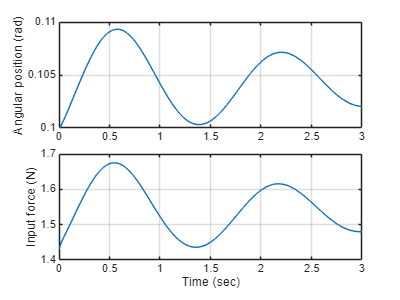

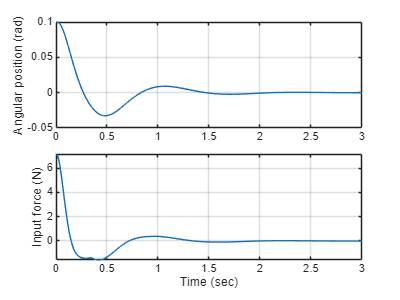

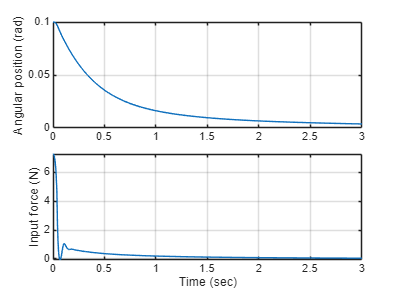

% open_system("pendulum_system");
for i = 1:length(deriv_gain_set)
    g0 = deriv_gain_set(i,1);
    g1 = deriv_gain_set(i,2);
    h = deriv_gain_set(i,3);
    settingstr = "_"+num2str(g0)+"_"+num2str(g1)+"_"+num2str(h);
    simPendulumSystem(fis,g0,g1,h,"figures/"+mdlName+settingstr+".svg");
end